# **IO107 - Analog Output Test**

This example shows you how to perform an output test with the IO107 I/O module to verify the analog functionality of an output channel.

The IO107 is a 16-bit analog module with 16 differential analog output channels**.**

The Simulink model used in this example features the [IO107 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io107_setup) and [IO107 Analog output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io107_analog_output) blocks.

## Test Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO107 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

- Oscilloscope

### Test Setup

On the terminal board of the IO107 I/O module, connect Pin 1 (Analog Output 01 (-)) to the probe ground and Pin 2 (Analog Output 01 (+)) to the probe input of the oscilloscope.

The complete pin mapping of the IO107 can be found in the documentation: [IO107 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io107_pin_mapping) 

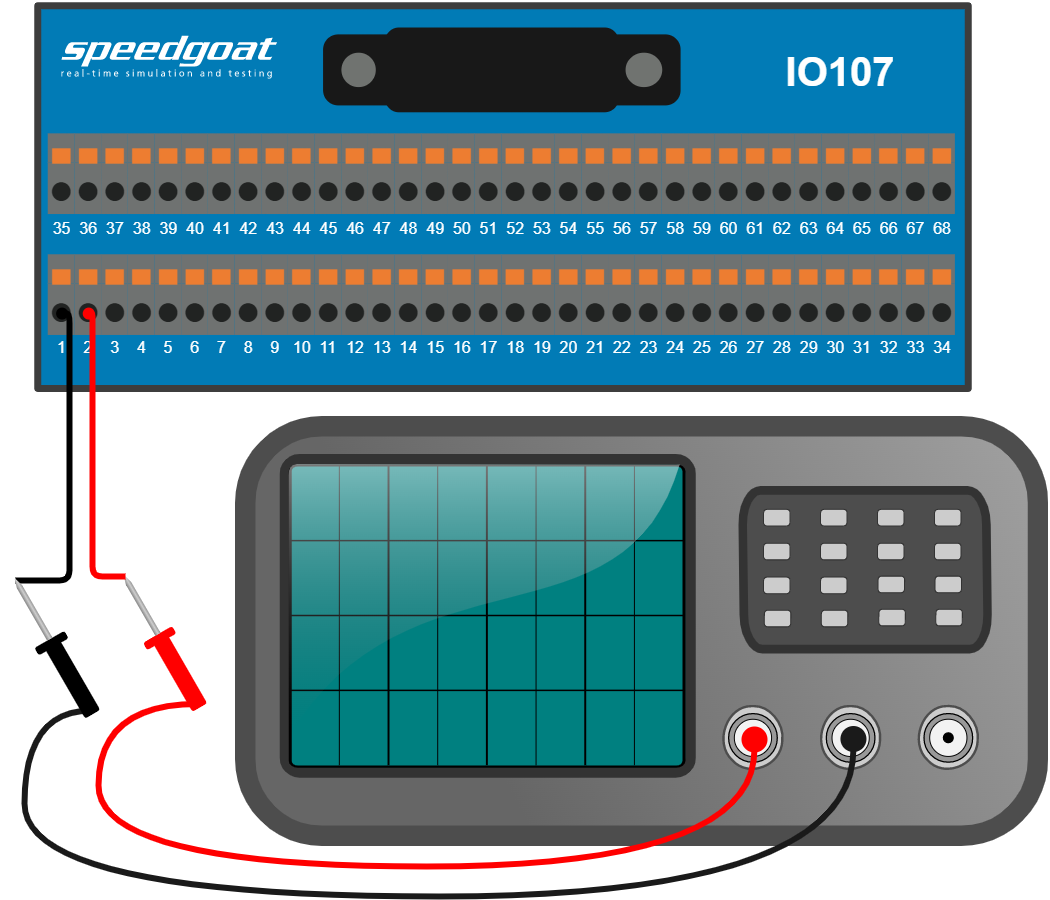

## Open Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO107_AnalogOutputTest';
open_system(modelName);         

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Results by Using an Oscilloscope

Once the real-time application runs, you should be able to see the output voltage from the IO107. The output signal is a sine wave with frequency = 15 Hz, amplitude +-9 V.

 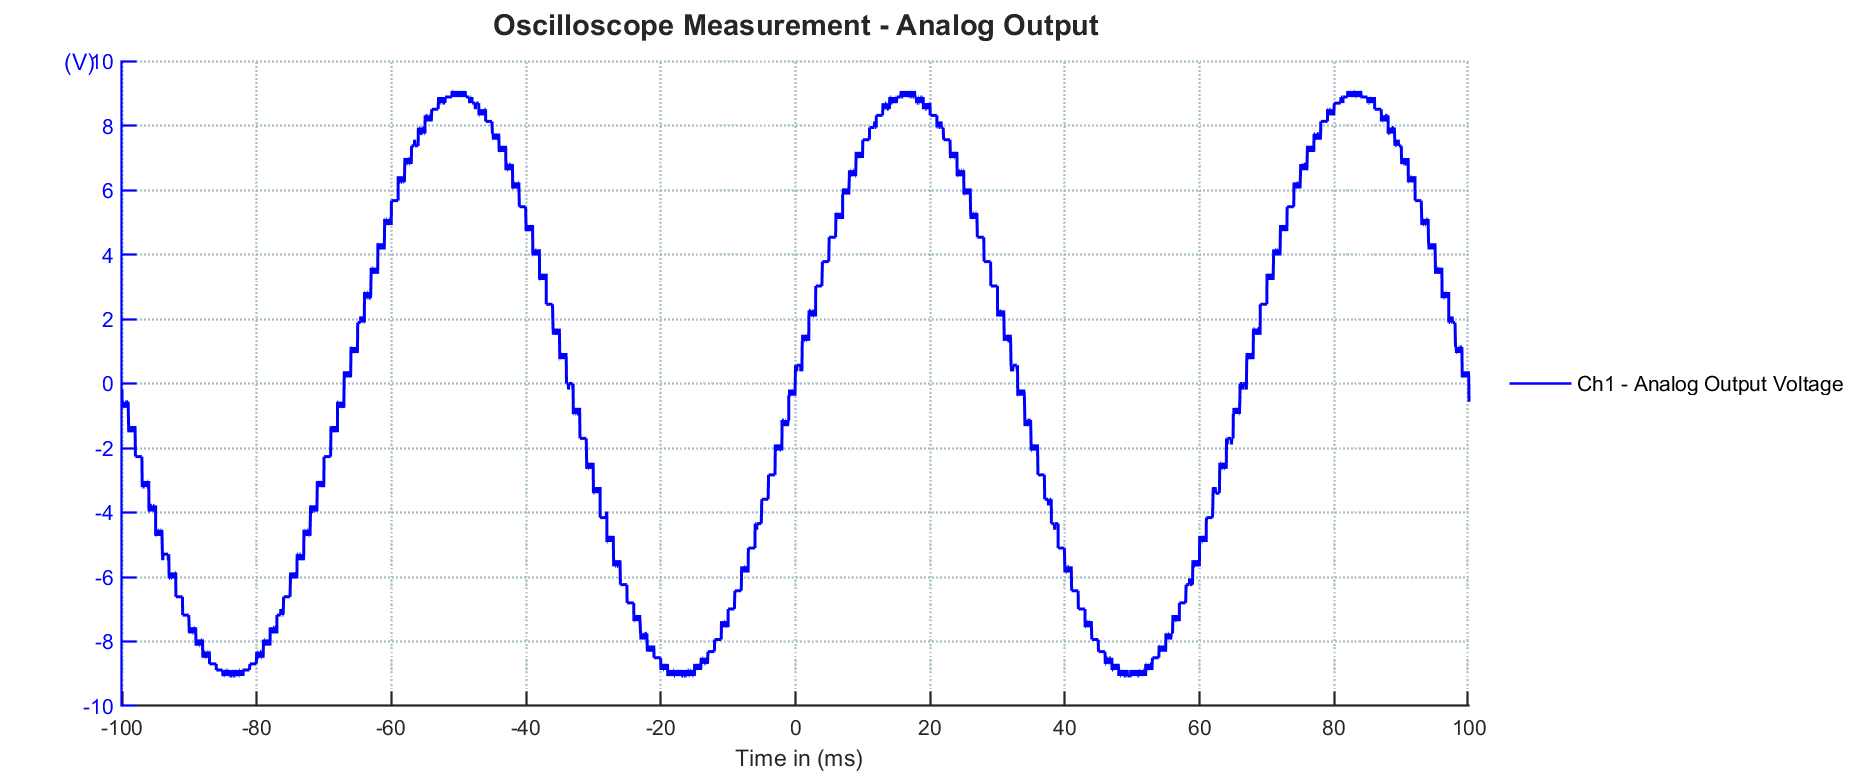

## Additional References

- [IO107 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io107)